% Script to simulate RLC circuit

## Initial constants

h = 1/(192*10^3); % h is 1/192k hz

kmax = 2880; % number of time steps

% components of circuit
% Green
R1 = 50;
L1 = 100*10^-3;
C1 = 0.1*10^-6;

% Components for other 2 circuits
% Red
R2 = 200;
L2 = 100*10^-3;
C2 = 0.1*10^-6;

% Purple
R3 = 30;
L3 = 100*10^-3;
C3 = 0.1*10^-6;


Vin = [0; ones(kmax, 1)];

Vc = 0;
I = 0;

% Matricies derived
x1 = [Vc, I; zeros(kmax, 2)];
A1 = [1, h/C1;
    -h/L1, 1-h*R1/L1];
B1 = [0; h/L1];

x2 = [Vc, I; zeros(kmax, 2)];
A2 = [1, h/C2;
    -h/L2, 1-h*R2/L2];
B2 = [0; h/L2];

x3 = [Vc, I; zeros(kmax, 2)];
A3 = [1, h/C3;
    -h/L3, 1-h*R3/L3];
B3 = [0; h/L3];

## Simulating as time goes on

for k=2:kmax
    x1(k, :) = A1*(x1(k-1, :)')+B1*Vin(k-1, :);
    x2(k, :) = A2*(x2(k-1, :)')+B2*Vin(k-1, :);
    x3(k, :) = A3*(x3(k-1, :)')+B3*Vin(k-1, :);
end

## Plotting

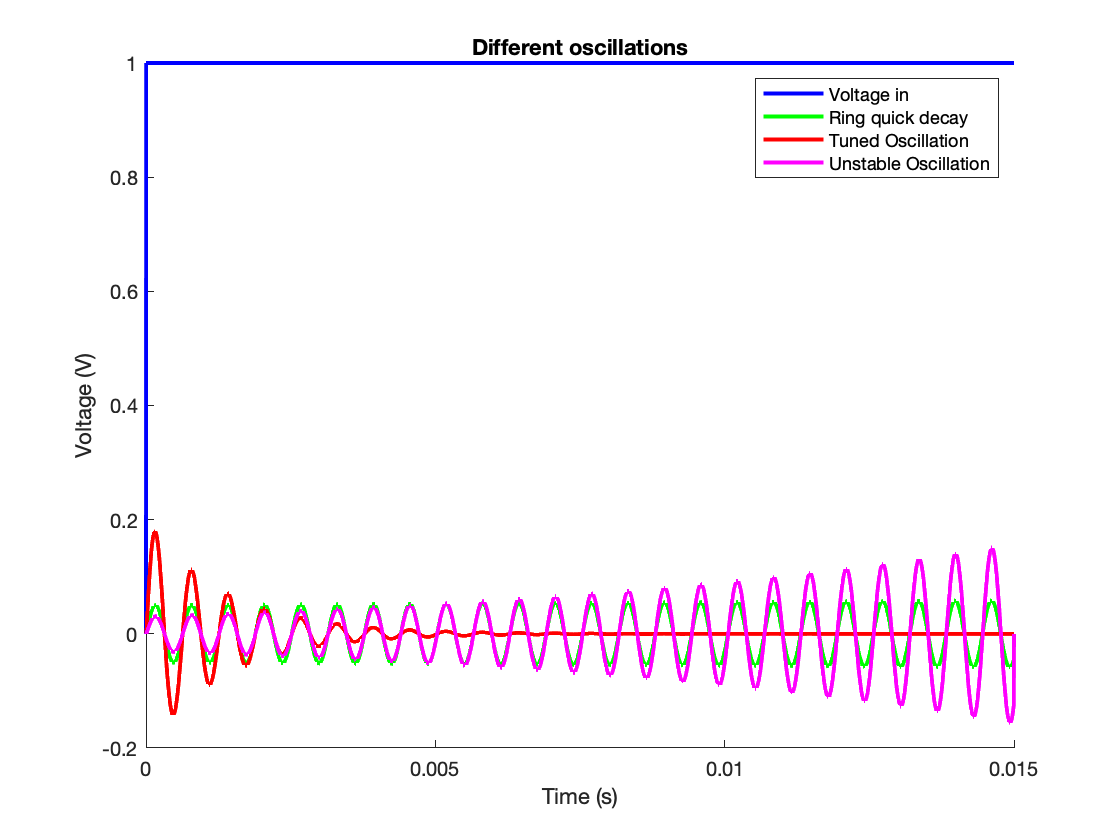

t = 0:h:kmax*h; % Make time vector

figure;
hold on;
plot(t, Vin(:, 1), 'b', 'linewidth',2);
plot(t, x1(:, 2)*R1, 'g', 'linewidth',2);
plot(t, x2(:, 2)*R2, 'r', 'linewidth',2);
plot(t, x3(:, 2)*R3, 'm', 'linewidth',2);
legend("Voltage in", "Ring quick decay", "Tuned Oscillation", "Unstable Oscillation");
ylabel("Voltage (V)");
xlabel("Time (s)");
title("Different oscillations");

## Questions

C changes how fast the oscillations dampen, and the decay. An increase in C causes the oscillations to dampen much quicker, and a smaller C causes oscillations to dampen slower. It also affects the amplitude of the graph.

% Changing R only changes how fast the oscillation dampens. A larger R
% makes the oscillations dampen faster, and a smaller R causes them to
% dampen slower.

% Changing L changes the period of the oscillation. A larger L value makes
% the period larger.

## Sounds

soundsc(x1); % Green
% Sounds like an even, low note
pause(1);
soundsc(x2); % Red
% Sounds like a quick, low note
pause(1);
soundsc(x3); % Purple
% Sounds like a note that is increasing in volume

## Responses

Setup like instructions

R = 10;
L = 200*10^-3;
C = 18*10^-6;

% R = 10;
% L = 200*10^-3;
% C = 18*10^-6

A = [1, h/C;
    -h/L, 1-h*R/L];
B = [0; h/L];

frequencies = [1400, 1500, 1600, 1800];

%Vins = zeros(kmax, numFrequency);
Vin1 = zeros(kmax+1, 1);
xf1 = [Vc, I; zeros(kmax, 2)];
for time = 1:kmax
    tabs = h*time;
    Vin1(time, :) = sin(2*pi*frequencies(1)*tabs);
    
    if time> 1
        xf1(time, :) = A*(xf1(time-1, :)')+B*Vin1(time-1, :);
    end
end
soundsc(xf1);
pause(1);

Vin2 = zeros(kmax+1, 1);
xf2 = [Vc, I; zeros(kmax, 2)];
for time = 1:kmax
    tabs = h*time;
    Vin2(time, :) = sin(2*pi*frequencies(2)*tabs);
    
    if time> 1
        xf2(time, :) = A*(xf2(time-1, :)')+B*Vin2(time-1, :);
    end
end
soundsc(xf2);
pause(1);

Vin3 = zeros(kmax+1, 1);
xf3 = [Vc, I; zeros(kmax, 2)];
for time = 1:kmax
    tabs = h*time;
    Vin3(time, :) = sin(2*pi*frequencies(3)*tabs);
    
    if time> 1
        xf3(time, :) = A*(xf3(time-1, :)')+B*Vin3(time-1, :);
    end
end
soundsc(xf3);
pause(1);

Vin4 = zeros(kmax+1, 1);
xf4 = [Vc, I; zeros(kmax, 2)];
for time = 1:kmax
    tabs = h*time;
    Vin4(time, :) = sin(2*pi*frequencies(4)*tabs);
    
    if time> 1
        xf4(time, :) = A*(xf4(time-1, :)')+B*Vin4(time-1, :);
    end
end
Vin4

Vin4 =     0.0589
    0.1175
    0.1758
    0.2334
    0.2903
    0.3461
    0.4007
    0.4540
    0.5057
    0.5556


xf4

xf4 =          0         0
         0    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0001
    0.0001    0.0001


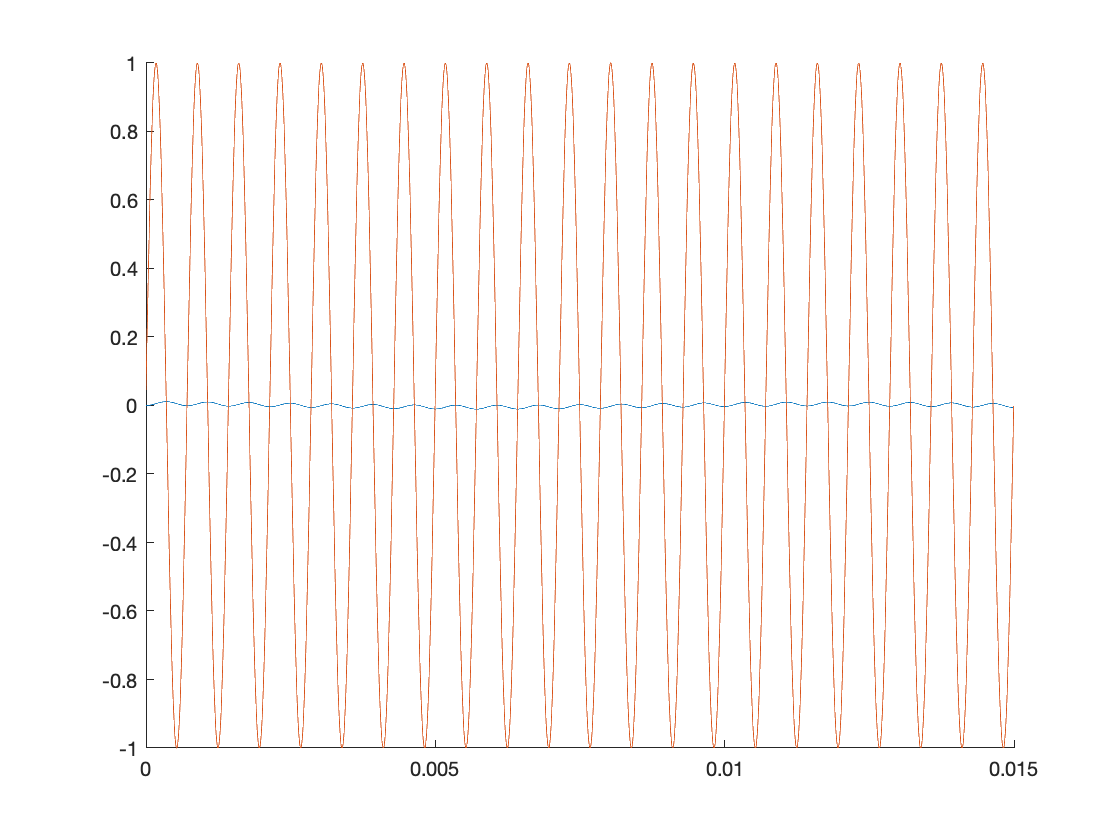

soundsc(xf4);
pause(1);

figure;
hold on;
plot(t, xf1(:, 2)*R);
plot(t, Vin1);

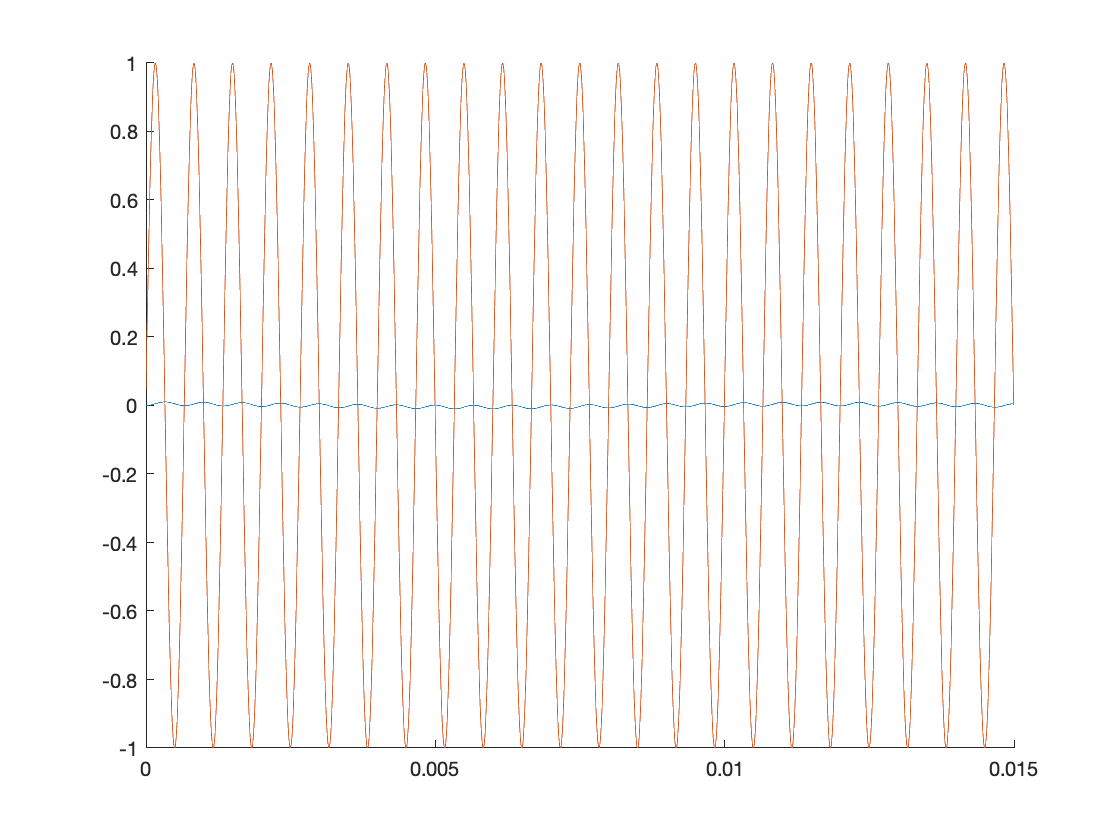


figure;
hold on;
plot(t, xf2(:, 2)*R);
plot(t, Vin2);

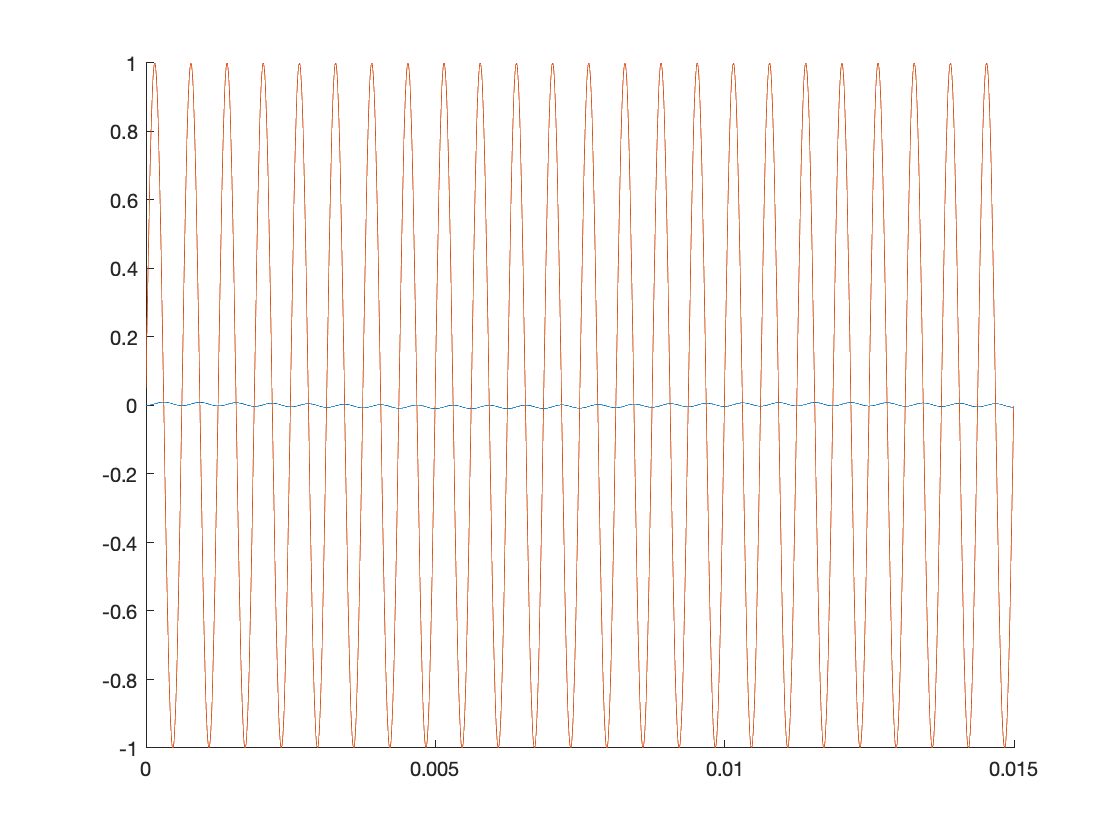


figure;
hold on;
plot(t, xf3(:, 2)*R);
plot(t, Vin3);

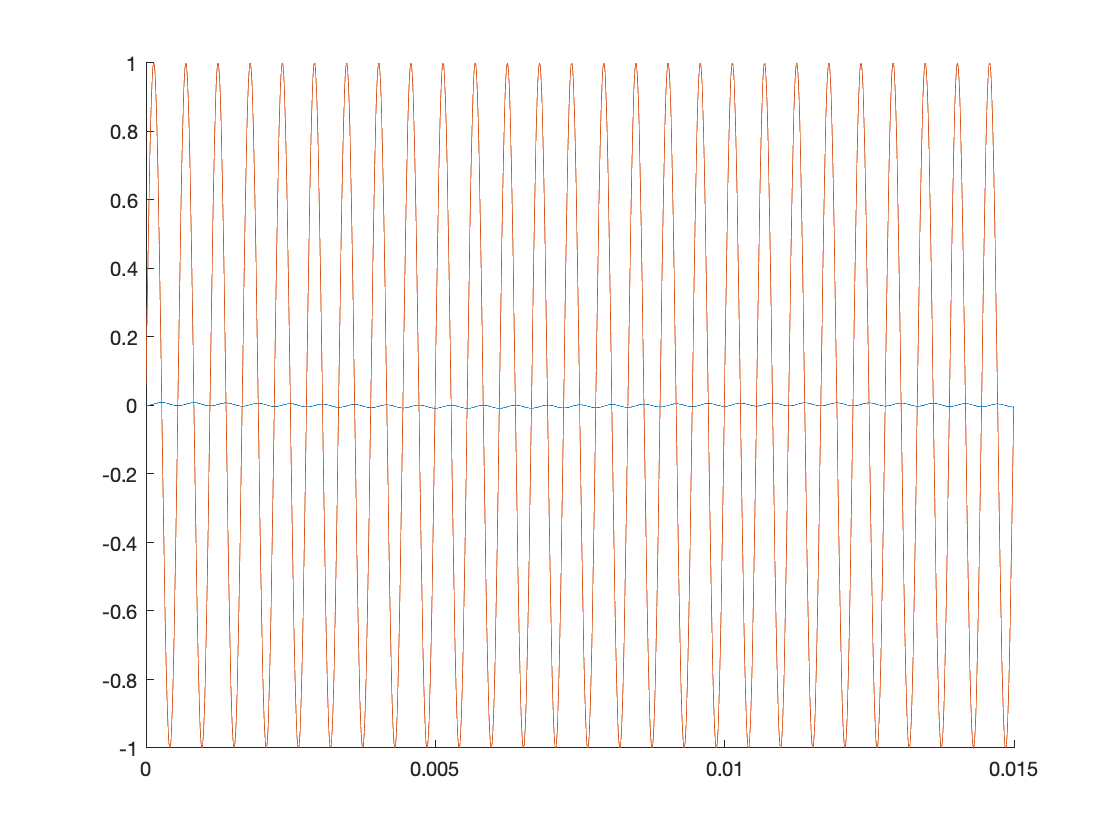


figure;
hold on;
plot(t, xf4(:, 2)*R);
plot(t, Vin4);

freqs = 10:5:5000

freqs =     10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175   180   185   190   195   200   205   210   215   220   225   230   235   240   245   250   255


amps = zeros(size(freqs))

amps =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


VinL = zeros(kmax+1, 1);
xfL = [Vc, I; zeros(kmax, 2)];
for f = 1:length(freqs)
    for time = 1:kmax
        tabs = h*time;
        VinL(time, :) = sin(2*pi*freqs(f)*tabs);
        
%         if time> 1
%             xfL(time, :) = A*(xfL(time-1, :)')+B*VinL(time-1, :);
%         end
%         amps(f) = max(xfL(:,2));
    end
    xfL = mySensorCircuit(VinL,h);
    amps(f) = max(xfL(:,2));
end

% NOW
% Test 84Hz Signal
for time = 1:kmax
    tabs = h*time;
    VinL(time, :) = sin(2*pi*84*tabs);
    
%     if time> 1
%         xfL(time, :) = A*(xfL(time-1, :)')+B*VinL(time-1, :);
%     end
end
xfL = mySensorCircuit(VinL,h);
figure;
hold on

size(VinL)

ans =         2881           1


size(xfL)

ans =         2881           2


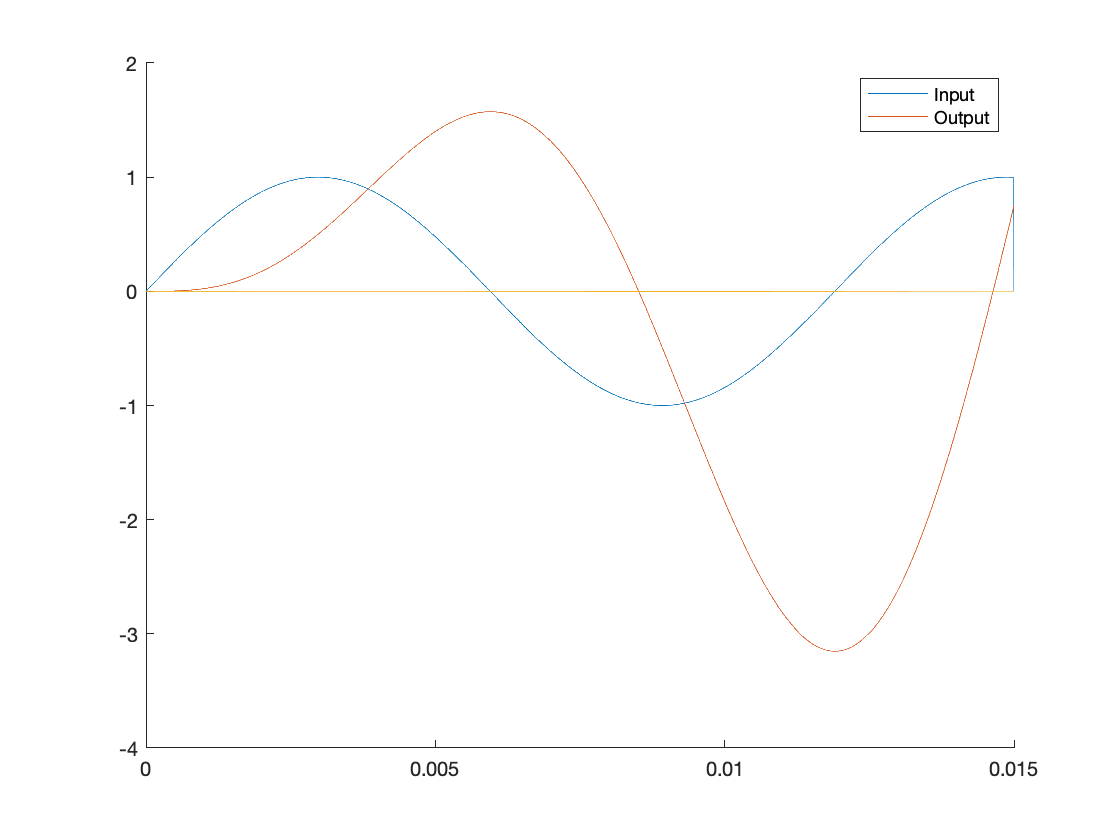



plot(t',VinL);
plot(t',xfL);
legend('Input','Output')

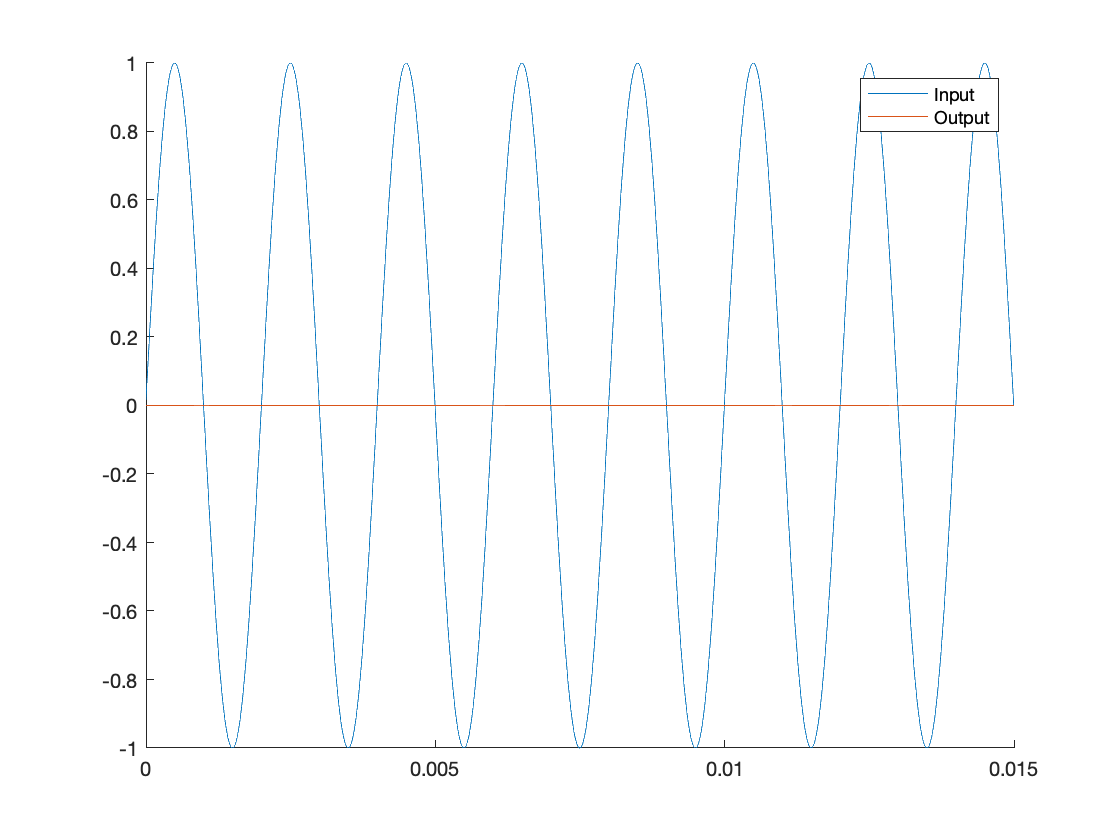



% Test 500Hz Signal
for time = 1:kmax
    tabs = h*time;
    VinL(time, :) = sin(2*pi*500*tabs);
    
%     if time> 1
%         xfL(time, :) = A*(xfL(time-1, :)')+B*VinL(time-1, :);
%     end
end
xfL = mySensorCircuit(VinL,h);
figure;
hold on
plot(t,VinL);
plot(t,xfL(:,2));
legend('Input','Output')

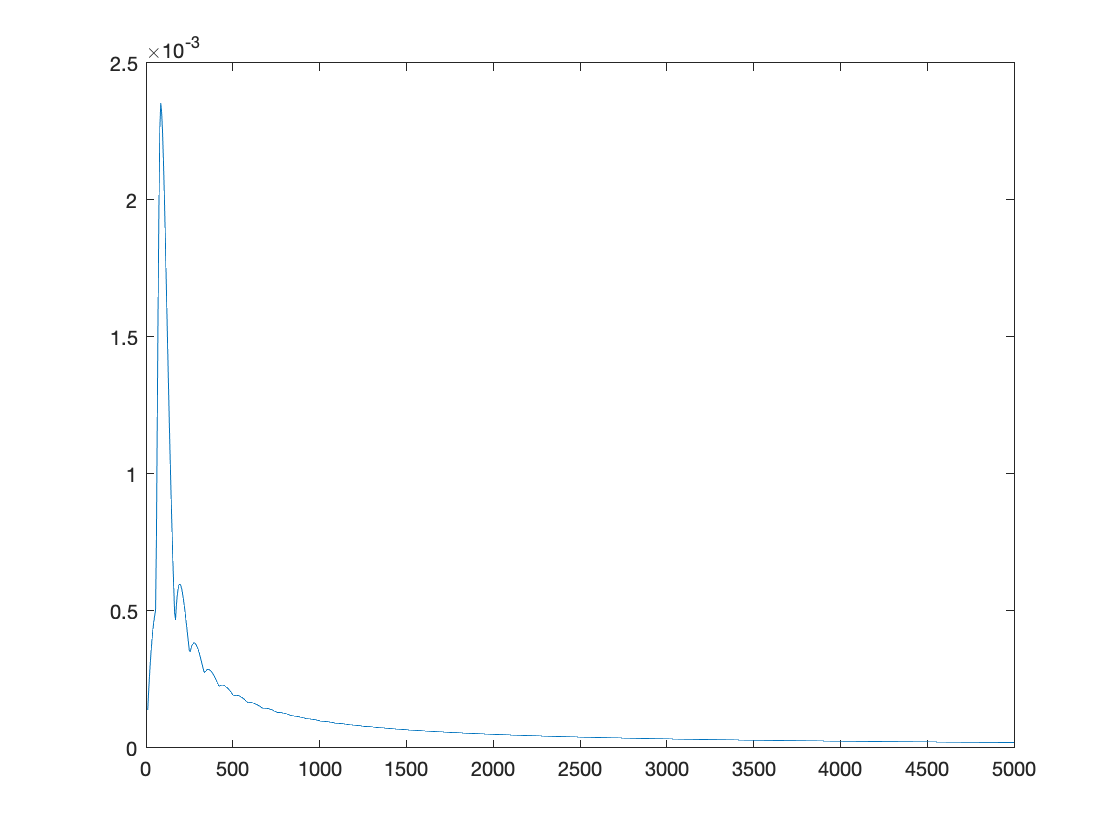



figure;
plot(10:5:5000,amps);

for time = 1:kmax*5
    tabs = h*time;
%     VinL(time, :) = sin(2*pi*84*tabs);
    VinL(time, :) = sin(2*pi*84*tabs);
    VinL(time, :) = VinL(time,:) + sin(2*pi*800*tabs);
%     VinL(time, :) = VinL(time,:) + sin(2*pi*5*tabs);
end
xfL = mySensorCircuit(VinL,h);
soundsc(VinL,1/h);
pause(1);
soundsc(xfL,1/h)
figure;
hold on;

size((0:h:(kmax*5*h)-h))

ans =            1       14400


size(VinL)

ans =        14400           1


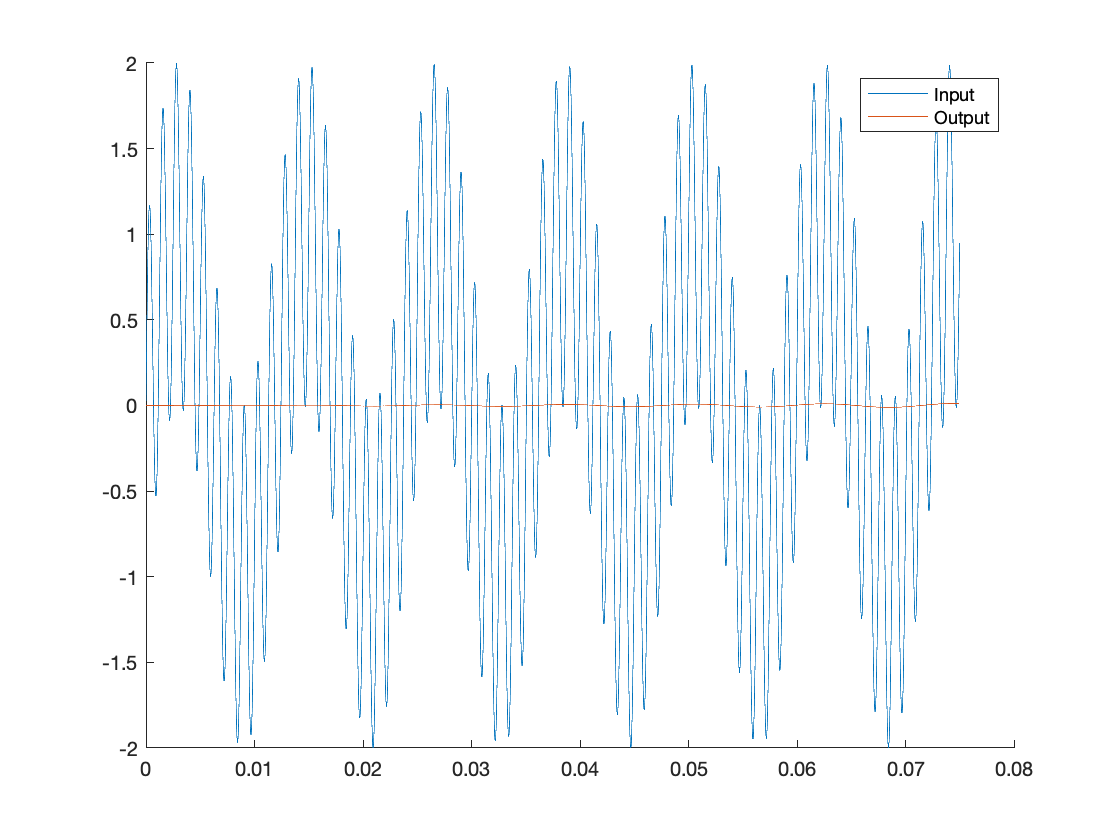


plot((0:h:(kmax*5*h)-h)',VinL);
plot((0:h:(kmax*5*h)-h)',xfL(:,2));
legend("Input","Output")

## Questions

The filter is a bandpass filter. Frequencies at a range around 1500 are allowed to pass, while all other frequencies have their amplitudes cut significantly

## You can fix this later, basically automated with diff num frequencies

numFrequency = size(frequencies, 2);

% Make array that is A repeated num frequency times multipleA = repmat({A}, 1, numFrequency); % Make 2*num x 2*num, where diag are A Aadjusted = blkdiag(multipleA{:});

Badjusted = B; input = [Vc, I]; for count = 1:numFrequency-1 Badjusted = [Badjusted; B]; input = [input, [Vc, I]]; end

Vins = zeros(kmax, numFrequency); % Vins with columns duplicated for later Vins2 = zeros(kmax, numFrequency*2); % Constructs the v in for every frequency we are testing for time = 1:kmax t = h*time; Vins(time, :) = sin(2.*pi.*frequencies.*t); for count = 1: numFrequency Vins2(time, count:count+1) = sin(2.*pi.*frequencies(count).*t); end end

% Make 2*num frequency columns (1 column for v, one for i) and k time rows xResponse = [input; zeros(kmax, numFrequency*2)]; for k=2: kmax xResponse(k, :) = Aadjusted*(xResponse(k-1, :)')+Badjusted.*Vins2(k-1, :)'; end